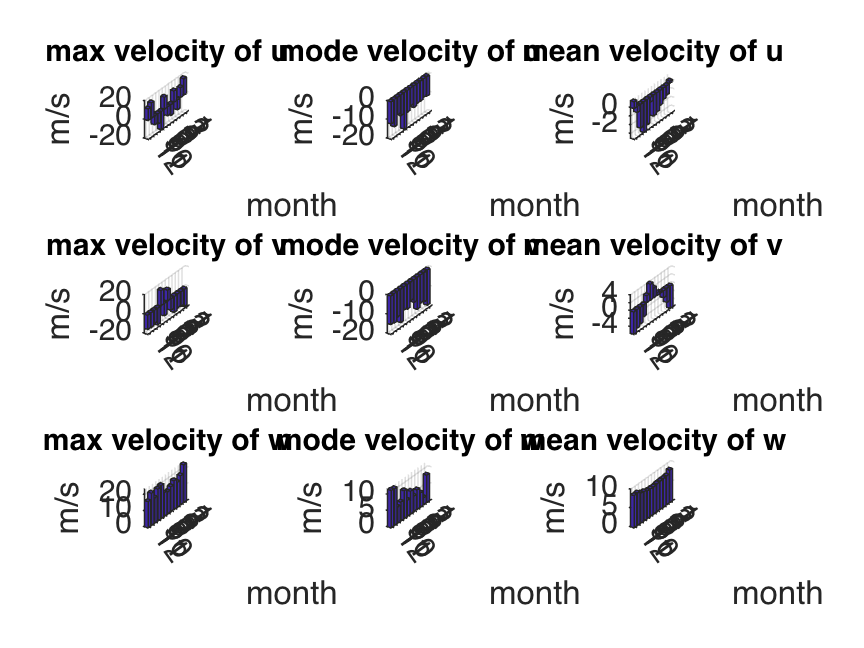

Mu=[];
Mv=[];
Mw=[];
for k = 0:11
    if k==0
       u1 = M(1:Ml(1),1);
       u1(u1<-9990) = [];
       v1 = M(1:Ml(1),2);
       v1(v1<-9990) = [];
       w1 = M(1:Ml(1),3);
       w1(w1<-9990) = [];
    else
       u1 = M(Ml(k)+1:Ml(k+1),1);
       u1(u1<-9990) = [];
       v1 = M(Ml(k)+1:Ml(k+1),2);
       v1(v1<-9990) = [];
       w1 = M(Ml(k)+1:Ml(k+1),3);
       w1(w1<-9990) = [];
    end 
    u111=max(u1); % max value
    v111=max(v1);
    w111=max(w1);
    u112=min(u1); % min value
    v112=min(v1);
    w112=min(w1);
    if u111>abs(u112)
        u11=u111;
    else
        u11=u112;
    end
    if v111>abs(v112)
        v11=v111;
    else
        v11=v112;
    end
    if w111>abs(w112)
        w11=w111;
    else
        w11=w112;
    end
    u12=mode(u1); % mode number
    v12=mode(v1);
    w12=mode(w1);
    u13=mean(u1); % mean number
    v13=mean(v1);
    w13=mean(w1);
    Mu = [Mu;u11,u12,u13];
    Mv = [Mv;v11,v12,v13];
    Mw = [Mw;w11,w12,w13];
end

figure()
subplot(331)
bar3(Mu(:,1))
view(35,30)
xlabel('u');ylabel('month');zlabel('m/s');
title("max velocity of u","FontSize",10)
subplot(332)
bar3(Mu(:,2))
view(35,30)
xlabel('u');ylabel('month');zlabel('m/s');
title("mode velocity of u","FontSize",10)
subplot(333)
bar3(Mu(:,3))
view(35,30)
xlabel('u');ylabel('month');zlabel('m/s');
title("mean velocity of u","FontSize",10)

subplot(334)
bar3(Mv(:,1))
view(35,30)
xlabel('v');ylabel('month');zlabel('m/s');
title("max velocity of v","FontSize",10)
subplot(335)
bar3(Mv(:,2))
view(35,30)
xlabel('v');ylabel('month');zlabel('m/s');
title("mode velocity of v","FontSize",10)
subplot(336)
bar3(Mv(:,3))
view(35,30)
xlabel('v');ylabel('month');zlabel('m/s');
title("mean velocity of v","FontSize",10)

subplot(337)
bar3(Mw(:,1))
view(35,30)
xlabel('w');ylabel('month');zlabel('m/s');
title("max velocity of w","FontSize",10)
subplot(338)
bar3(Mw(:,2))
view(35,30)
xlabel('w');ylabel('month');zlabel('m/s');
title("mode velocity of w","FontSize",10)
subplot(339)
bar3(Mw(:,3))
view(35,30)
xlabel('w');ylabel('month');zlabel('m/s');
title("mean velocity of w","FontSize",10)